%% ------------------------------------------------
%   SIMULATION IEEE 802.11 Wi-Fi AVEC MATLAB
%   Par : [Votre Nom]
%   Objectif : Simuler un réseau Wi-Fi avec APs et Stations
%% ------------------------------------------------


clc; clear; close all;

%% Étape 1 : Définition des paramètres système
numAPs = 2;                   % Nombre d'Access Points (APs)
numStations = 10;             % Nombre de stations (clients)
channelBandwidth = 20e6;      % Bande passante du canal (20 MHz)
dataRate = 54e6;              % Débit de transmission (54 Mbps - 802.11g)
transmitPower = 20;           % Puissance d'émission (dBm)
snr = 20;                     % Rapport signal/bruit (SNR) en dB
packetSize = 1500 * 8;        % Taille des paquets (bits)


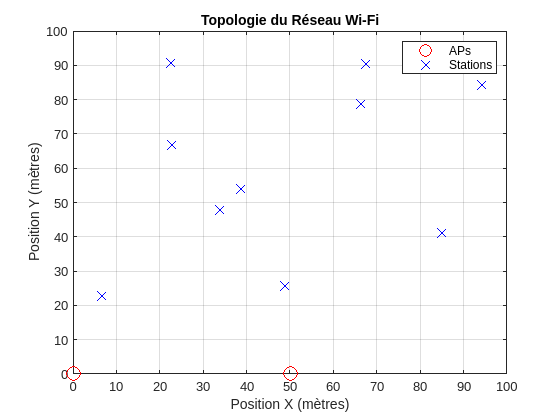

%% Étape 2 : Création de la topologie Wi-Fi (APs et stations)
% Positions des APs (AP1 à (0,0) et AP2 à (50,0))
apPositions = [0, 0; 50, 0];  

% Positions aléatoires des stations dans une zone 100x100m
stationPositions = 100 * rand(numStations, 2);  

% Affichage de la topologie du réseau Wi-Fi
figure;
plot(apPositions(:,1), apPositions(:,2), 'ro', 'MarkerSize', 10, 'DisplayName', 'APs'); hold on;
plot(stationPositions(:,1), stationPositions(:,2), 'bx', 'MarkerSize', 8, 'DisplayName', 'Stations');
legend('APs', 'Stations');
title('Topologie du Réseau Wi-Fi');
xlabel('Position X (mètres)');
ylabel('Position Y (mètres)');
grid on;

%% Étape 3 : Simulation de la transmission PHY avec 802.11n (BPSK)
% Configuration IEEE 802.11n
cfgVHT = wlanVHTConfig;
cfgVHT.ChannelBandwidth = 'CBW20';  % Canal 20 MHz
cfgVHT.NumTransmitAntennas = 1;     % Une seule antenne
cfgVHT.MCS = 0;                     % Modulation BPSK, taux de codage 1/2

% Génération de données aléatoires
psduLength = 1000;  % Longueur du PSDU en octets
psdu = randi([0 1], psduLength * 8, 1);  

% Modulation du signal
txWaveform = wlanWaveformGenerator(psdu, cfgVHT);

% Passage du signal dans un canal avec bruit AWGN
rxWaveform = awgn(txWaveform, snr, 'measured');

% Décodage des données reçues
rxPSDU = wlanVHTDataDecode(rxWaveform, cfgVHT, 0);

Unrecognized function or variable 'wlanVHTDataDecode'.


% Calcul du taux d'erreur binaire (BER)
[numErrors, ber] = biterr(psdu, rxPSDU);
disp(['Bit Error Rate (BER) : ', num2str(ber)]);

%% Étape 4 : Simulation du MAC Layer avec CSMA/CA
cwMin = 15;   % Fenêtre de contention minimale
cwMax = 1023; % Fenêtre de contention maximale
backoffTime = randi([0 cwMin], 1, numStations);  % Temps de backoff initial

% Simulation d'une transmission avec CSMA/CA
disp('Simulation de la transmission CSMA/CA :');
for i = 1:numStations
    if backoffTime(i) == 0
        disp(['Station ', num2str(i), ' transmet un paquet']);
        % Reset du backoff après transmission
        backoffTime(i) = randi([0 cwMin], 1);  
    else
        backoffTime(i) = backoffTime(i) - 1;  
    end
end


%% Étape 5 : Simulation de l'interférence et calcul du SNR
interferencePower = 5;  % Puissance d'interférence (dBm)
receivedPower = transmitPower - 20 * log10(norm([apPositions(1,:) - stationPositions(1,:)]));  
actualSNR = receivedPower - interferencePower;
disp(['SNR à la Station 1 : ', num2str(actualSNR), ' dB']);


%% Étape 6 : Calcul du Throughput
packetTransmissionTime = packetSize / dataRate;  % Temps pour transmettre un paquet
successfulPackets = 100;  % Nombre de paquets transmis avec succès
totalTime = successfulPackets * packetTransmissionTime;
throughput = (successfulPackets * packetSize) / totalTime;  % Débit en bits/s
disp(['Débit réseau : ', num2str(throughput / 1e6), ' Mbps']);


%% Étape 7 : Simulation du trafic réseau avec Poisson
lambda = 10;  % Taux moyen d'arrivée des paquets (paquets/sec)
traffic = poissrnd(lambda, 1, numStations);
disp('Taux d’arrivée des paquets pour chaque station :');
disp(traffic);


%% Étape 8 : Simulation de la QoS (802.11e)
trafficClasses = {'Voix', 'Vidéo', 'Best Effort'};
priorities = [1, 2, 3];  % Priorité (1 = plus haute)
stationTrafficClass = randi([1 3], numStations, 1);
[~, sortedIndices] = sort(priorities(stationTrafficClass));  
disp('Stations servies dans l’ordre de priorité :');
disp(sortedIndices');


%% Étape 9 : Visualisation des performances réseau
% Calcul du throughput pour chaque station (valeurs aléatoires simulées)
stationThroughput = throughput * rand(1, numStations);


% Affichage sous forme de barres
figure;
bar(stationThroughput / 1e6);  % Conversion en Mbps
title('Débit du Réseau Wi-Fi par Station');
xlabel('Station');
ylabel('Débit (Mbps)');
grid on;

